# Dynamics Simulation 

Dynamic Simulation for the 2 DoF Space Robot

clc
load 'SC_2DoF.mat'

sc.homeConfig();

Specify Forces

f0 = [0; 0; 0];     % Forces on base [fx, fy, fz], in base frame
n0 = [0; 0; 0];     % Torques on base [nx, ny, nz], in base frame
tau_qm = [0; 1];      % Joint torques

### Launch Simulation

tic
sim('sim_test')
toc

### Animate Results

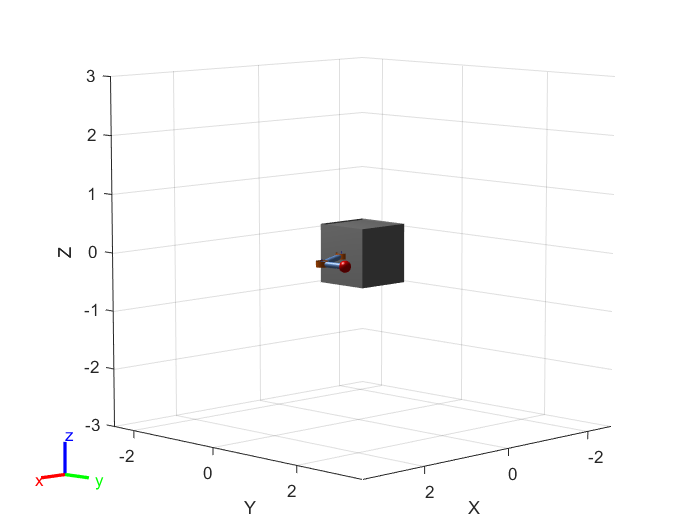

framesPerSecond = 55;
r = rateControl(framesPerSecond);
for i = 1:length(out.q.Time)
    sc.q = out.q.Data(:, :, i);
    sc.show('PreservePlot',false, 'Visuals', 'off');
    drawnow
    waitfor(r);
end